pcdDir = "/Users/ikuta/Documents/Projects/wildpose-self-calibrator/data/martial_eagle/lidar/";
pcdFileNames = [
    "livox_frame_1670316371_416378416.pcd"
    "livox_frame_1670316371_517465712.pcd"
    "livox_frame_1670316371_617302160.pcd"
    "livox_frame_1670316371_717487632.pcd"
    "livox_frame_1670316371_817358256.pcd"
    "livox_frame_1670316371_916403504.pcd"
    "livox_frame_1670316372_017466128.pcd"
    "livox_frame_1670316372_117501424.pcd"
    "livox_frame_1670316372_217646640.pcd"
    "livox_frame_1670316372_317414576.pcd"
    "livox_frame_1670316372_416408496.pcd"
    "livox_frame_1670316372_517364912.pcd"
    "livox_frame_1670316372_617444208.pcd"
    "livox_frame_1670316372_717515888.pcd"
    "livox_frame_1670316372_817410960.pcd"
    "livox_frame_1670316372_916385232.pcd"
    "livox_frame_1670316373_017311792.pcd"
    "livox_frame_1670316373_116479760.pcd"
    "livox_frame_1670316373_217650416.pcd"
    "livox_frame_1670316373_317481392.pcd"
    "livox_frame_1670316373_417421264.pcd"
    "livox_frame_1670316373_516967536.pcd"
    "livox_frame_1670316373_616309744.pcd"
    "livox_frame_1670316373_717420880.pcd"
    "livox_frame_1670316373_817867952.pcd"
]

pcdFileNames = 25×1 string array
    "livox_frame_1670316371_416378416.pcd"
    "livox_frame_1670316371_517465712.pcd"
    "livox_frame_1670316371_617302160.pcd"
    "livox_frame_1670316371_717487632.pcd"
    "livox_frame_1670316371_817358256.pcd"
    "livox_frame_1670316371_916403504.pcd"
    "livox_frame_1670316372_017466128.pcd"
    "livox_frame_1670316372_117501424.pcd"
    "livox_frame_1670316372_217646640.pcd"
    "livox_frame_1670316372_317414576.pcd"
    "livox_frame_1670316372_416408496.pcd"
    "livox_frame_1670316372_517364912.pcd"
    "livox_frame_1670316372_617444208.pcd"
    "livox_frame_1670316372_717515888.pcd"
    "livox_frame_1670316372_817410960.pcd"
    "livox_frame_1670316372_916385232.pcd"
    "livox_frame_1670316373_017311792.pcd"
    "livox_frame_1670316373_116479760.pcd"
    "livox_frame_1670316373_217650416.pcd"
    "livox_frame_1670316373_317481392.pcd"
    "livox_frame_1670316373_417421264.pcd"
    "livox_frame_1670316373_516967536.pcd"
    "livox_frame_1670

## Visualization

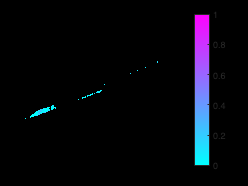

% Initialize ptCloud using the first file
filepath = fullfile(pcdDir, pcdFileNames(1));
ptCloud = pcread(filepath);

% Load and merge the next set of point clouds
for i = 2:length(pcdFileNames)
    filepath = fullfile(pcdDir, pcdFileNames(i));
    tmpPtCloud = pcread(filepath);
    ptCloud = pcmerge(ptCloud, tmpPtCloud, 0.001); % Using a merge tolerance of 0.001, adjust accordingly
end

pcshow(ptCloud.Location, ptCloud.Intensity / max(ptCloud.Intensity))
title(filepath, 'Interpreter','none')
xlabel("X")
ylabel("Y")
zlabel("Z")
colorbar
colormap("cool")

pcwrite(ptCloud, "/Users/ikuta/Documents/Projects/wildpose-self-calibrator/data/martial_eagle/accumulation.pcd")